# Plot ROS Bag

Copyright 2021, The MathWorks, Inc

This live script shows how to extract data from a ROS Bag file in order to plot odometry information from a robot. For more information on how to use rosbags in MATLAB® visit the [documentation for ROS Log Files](https://www.mathworks.com/help/ros/log-files-and-transformations.html).

### Import ROS Bag to MATLAB

bag = rosbag('ROSBag_turtleBotMaze.bag');

### Select and Process Data of Interest

odomData = select(bag,'Time',[bag.StartTime bag.StartTime+180],'Topic','/odom');
pose = timeseries(odomData,'Pose.Pose.Position.X','Pose.Pose.Position.Y');
rotationRaw = timeseries(odomData,'Pose.Pose.Orientation.X','Pose.Pose.Orientation.Y','Pose.Pose.Orientation.Z','Pose.Pose.Orientation.W');
rotation = quat2eul(rotationRaw.Data);

### Plot Robot Trajectory

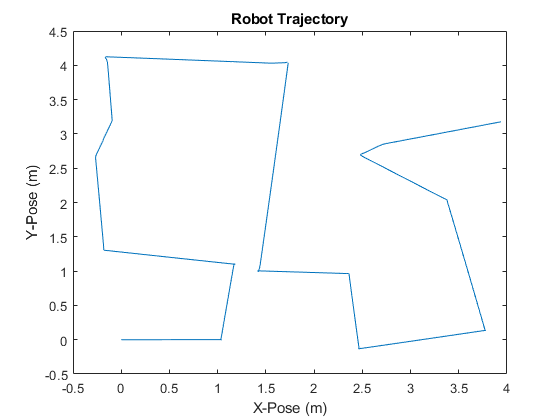

plot(pose.Data(:,1),pose.Data(:,2))
title('Robot Trajectory')
xlabel('X-Pose (m)')
ylabel('Y-Pose (m)')

### Plot Robot Orientation vs Time

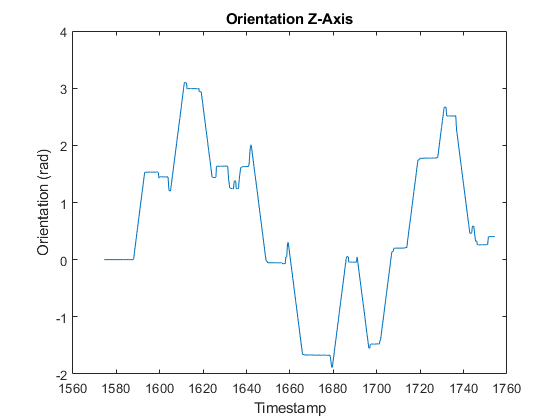

plot(rotationRaw.Time,rotation(:,3))
title('Orientation Z-Axis')
xlabel('Timestamp')
ylabel('Orientation (rad)')